## Computer Assignment 4

Shun Iwata

ID: 28699490

x1=[-2.4061 -1.083 -0.644 -0.4068 -0.2448 -0.1158];
for i=1:length(x1)
    x2(i)=-x1(length(x1)-i+1);
end
y1=[-0.3984 -0.7611 -0.9688 -0.9791 -0.7899 -0.4397];
for i=1:length(y1)
    y2(i)=-y1(length(y1)-i+1);
end
X=[x1 0 x2];
Y=[y1 0 y2];

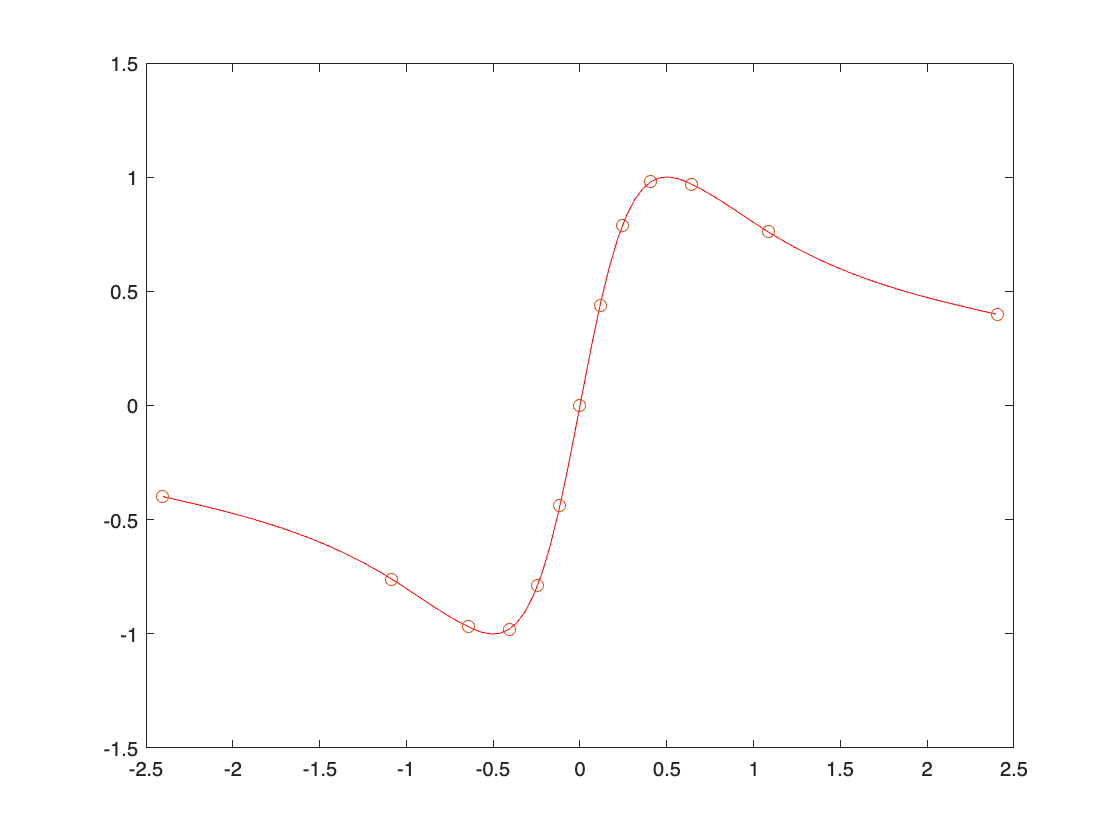

x=linspace(-2.4,2.4,100);
for i=1:length(x)
    y(i)=Cubic_Spline(X,Y,x(i));
end

plot(x,y,"-r")
hold on 
plot(X,Y,'o')

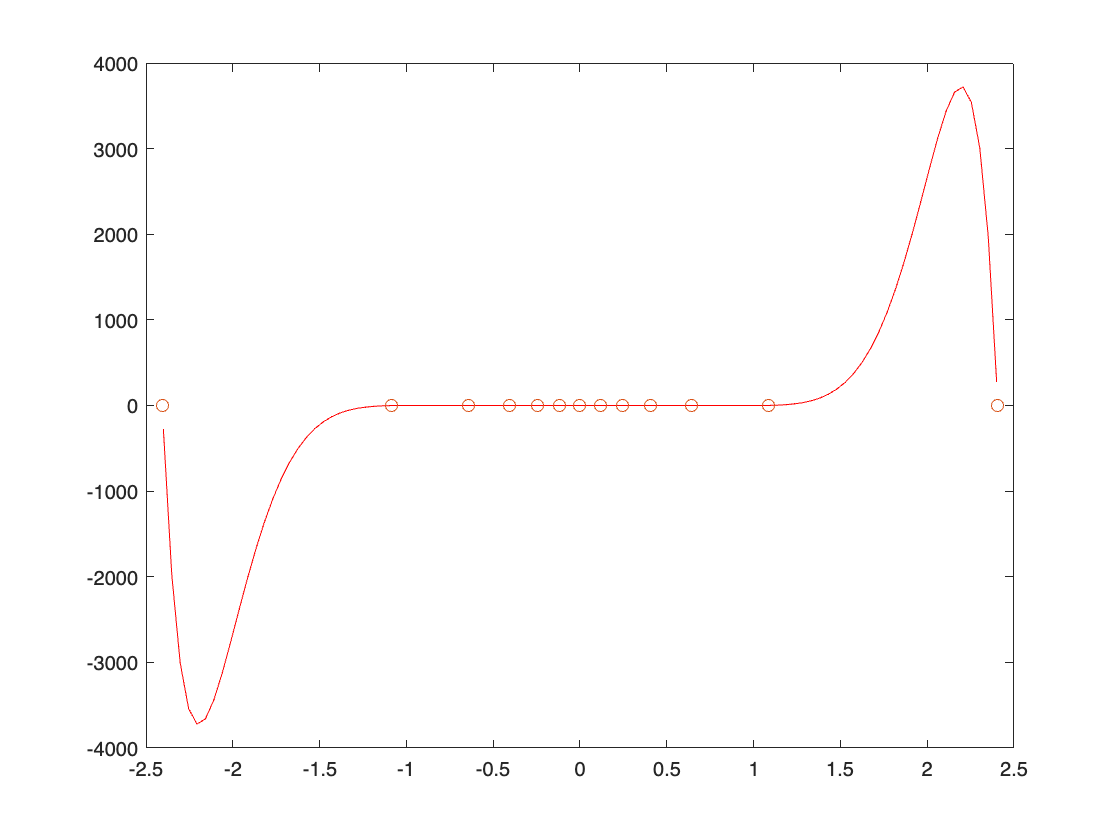

x1=x;
for i=1:length(x1)
    y1(i)=f_lagrange(X,Y,x1(i));
end
figure

plot(x1,y1,'-r')
hold on 
plot(X,Y,'o')

Cubic Spline is more accurate than the Lagrange interpolation since as you can see in the graph, Lagrange interpolation takes extreme value close to -4000 and 4000, which is probably not correct. Also, as you zoom into the interpolation points, some of the points are slightly off from the polynomial. 

function y=f_lagrange(a,b,c)
s=0;
    for i=1:length(a)
    u=1;
    l=1;
     for j=1:length(a)
        if j ~= i
            u = u * (c - a(j));
            l = l * (a(i) - a(j));
        end
     end
    s=s+u/l* b(i);
    end
    y=s;
end

function y=Cubic_Spline(X,Y,x)
n=length(X)-1;
for i=1:n
    h(i)=X(i+1)-X(i);
end
for i=2:n
    alpha(i)=3/h(i)*(Y(i+1)-Y(i))-3/h(i-1)*(Y(i)-Y(i-1));
end
l(1)=1;mu(1)=0;z(1)=0;
for i=2:n
    l(i)=2*(X(i+1)-X(i-1))-h(i-1)*mu(i-1);
    mu(i)=h(i)/l(i);
    z(i)=(alpha(i)-h(i-1)*z(i-1))/l(i);
end
l(n+1)=1;z(n+1)=0;c(n+1)=0;
for j=1:n
    c(n-j+1)=z(n-j+1)-mu(n-j+1)*c(n-j+2);
    b(n-j+1)=(Y(n-j+2)-Y(n-j+1))/h(n-j+1)-h(n-j+1)*(c(n-j+2)+2*c(n-j+1))/3;
    d(n-j+1)=(c(n-j+2)-c(n-j+1))/(3*h(n-j+1));
end
a=Y(1:end-1);
c=c(1:end-1);
for i=1:n
    if x>=X(i) && x<=X(i+1)
        break
    end
end
y = a(i)+b(i)*(x-X(i))+c(i)*(x-X(i))^2+d(i)*(x-X(i))^3;
end
 